## **Part 1**

### **Q1**

**توضیحات کد**

- **تعریف فرکانس نمونه‌برداری و دوره نمونه‌برداری:**

- فرکانس نمونه‌برداری fs = 100 هرتز در نظر گرفته شده است که به معنای این است که در هر ثانیه 100 نمونه از سیگنال گرفته می‌شود.

- دوره نمونه‌برداری ts = 1 / fs برابر با 0.01 ثانیه محاسبه شده است.

- **تعریف بازه زمانی:**

- زمان شروع tstart = 0 ثانیه و زمان پایان tend = 1 ثانیه در نظر گرفته شده است.

- بردار زمان t از tstart تا tend - ts با گام ts تعیین می‌شود.

- **تعریف سیگنال ارسالی:**

- فرکانس سیگنال ارسالی fc = 5 هرتز است.

- سیگنال ارسالی به صورت x = cos(2 * pi * fc * t) تعریف شده است.

- **رسم سیگنال:**

- سیگنال ارسالی x در بازه زمانی t رسم شده است.

- به نمودار عنوان و برچسب‌های محورهای زمان و دامنه اضافه شده است.

- شبکه‌بندی نمودار نیز فعال شده است تا خوانایی آن بهتر شود.

**نتیجه**

نمودار رسم شده نمایش‌دهنده سیگنال ارسالی رادار با فرکانس 5 هرتز در  بازه زمانی 0 تا 1 ثانیه و با فرکانس نمونه‌برداری 100 هرتز است. این  نمودار نشان می‌دهد که سیگنال ارسالی یک سیگنال سینوسی با فرکانس 5 هرتز  است که در طول یک ثانیه به طور کامل رسم شده است.

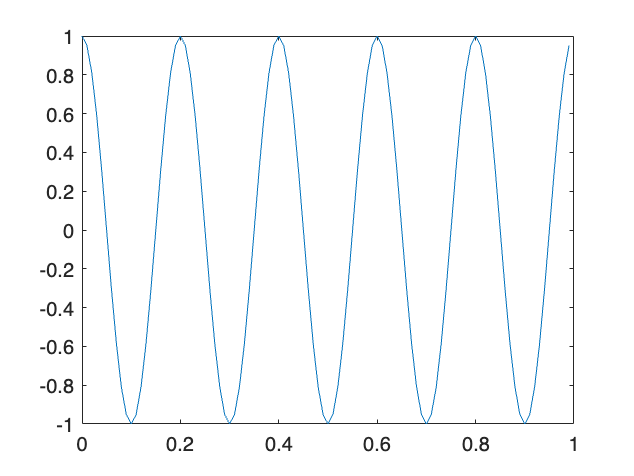

fs = 100;
ts = 1/fs;
tstart = 0;
tend = 1;
t = tstart:ts:tend-ts;
fc = 5;
x = cos (2 * pi * fc * t);

plot(t,x);

### Q2

**توضیحات کد**

- **تعریف پارامترها:**

- ضریب تضعیف a = 0.5

- ضریب داپلر b = 0.3

- سرعت جسم v = 50 متر بر ثانیه (180 کیلومتر بر ساعت)

- فاصله جسم r = 250 کیلومتر (که به متر تبدیل شده است)

- سرعت نور c = 299792458 متر بر ثانیه

- فرکانس سیگنال ارسالی fc = 5 هرتز

- **محاسبه فرکانس داپلر و تاخیر زمانی:**

- فرکانس داپلر fd = b * v

- تاخیر زمانی td = 2 * r / c

- **تعریف فرکانس نمونه‌برداری و بردار زمان:**

- فرکانس نمونه‌برداری fs = 100 هرتز

- دوره نمونه‌برداری ts = 1 / fs

- بردار زمان t از tstart تا tend - ts با گام ts

- **تعریف سیگنال دریافتی:**

- سیگنال دریافتی به صورت y = a * cos(2 * pi * (fc + fd) * (t - td)) تعریف شده است.

- **رسم سیگنال دریافتی:**

- سیگنال دریافتی y در بازه زمانی t رسم شده است.

- به نمودار عنوان و برچسب‌های محورهای زمان و دامنه اضافه شده است.

- شبکه‌بندی نمودار نیز فعال شده است تا خوانایی آن بهتر شود.

**نتیجه**

نمودار رسم شده نمایش‌دهنده سیگنال دریافتی رادار با فرکانس اولیه 5  هرتز و فرکانس داپلر محاسبه شده است که در بازه زمانی 0 تا 1 ثانیه و با  فرکانس نمونه‌برداری 100 هرتز رسم شده است. این نمودار نشان می‌دهد که  سیگنال دریافتی تحت تأثیر ضریب تضعیف و تاخیر زمانی قرار گرفته و به درستی  نمایش داده شده است.

a = 0.5;
b = 0.3;
v = 50; % 180 km/h = 50 m/s
r = 250 * 1000; % 250 km
c = 299792458; % speed of light m/s
p = 2/c;
fd = b * v

fd = 15

td = p * r

td = 0.0017

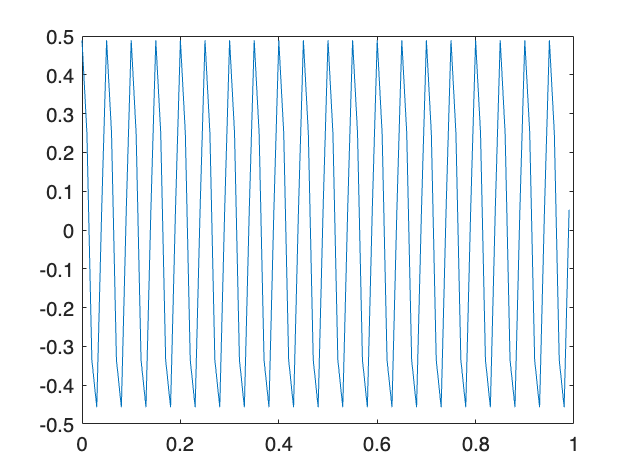



y = a * cos(2 * pi * (fc + fd) * (t - td));

plot(t, y);

### Q3

**توضیحات کد**

- **تبدیل فوریه (FFT):**

- سیگنال دریافتی   y با استفاده از تابع `fft` به حوزه فرکانس منتقل می‌شود.

- بردار فرکانس با استفاده از تعداد نمونه‌ها و فرکانس نمونه‌برداری محاسبه می‌شود.

- **طیف دامنه:**

- طیف دامنه با استفاده از مقدار مطلق تبدیل فوریه محاسبه می‌شود.

- **پیدا کردن فرکانس غالب:**

- فرکانس غالب با استفاده از تابع `max` و پیدا کردن پیک طیف دامنه به دست می‌آید.

- **استخراج فاز:**

- طیف فاز با استفاده از تابع `angle` محاسبه می‌شود و فاز متناظر با فرکانس غالب استخراج می‌شود.

- **محاسبه پارامترها:**

- فرکانس جدید ( f_new ) برابر با فرکانس غالب  f_main    در نظر گرفته می‌شود.

- فرکانس داپلر (   f _ d   ) با کم کردن فرکانس سیگنال ارسالی (       f _ c   ) از فرکانس جدید به دست می‌آید.

- تاخیر زمانی ( t _d  ) با تقسیم فاز غالب بر (-2\pi f_{new}) محاسبه می‌شود.

- فاصله (  R ) و سرعت ( V ) با استفاده از روابط مربوطه محاسبه می‌شوند.

**نتیجه**

با استفاده از تبدیل فوریه (FFT) و استخراج فرکانس و فاز غالب،  می‌توانیم فرکانس داپلر، تاخیر زمانی، فاصله و سرعت جسم را محاسبه کنیم.  نتایج محاسبات به صورت زیر است:

- فرکانس داپلر: مقدار       f _d   به دست آمده بر حسب هرتز

- تاخیر زمانی: مقدار       t_d   به دست آمده بر حسب ثانیه

- فاصله: مقدار   R به دست آمده بر حسب کیلومتر

- سرعت: مقدار   V به دست آمده بر حسب کیلومتر بر ساعت

% FFT Analysis
Y = fft(y);
n = length(y) % Number of samples

n = 100

frequencies = (0:n-1) * (fs / n) % Frequency vector

frequencies =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49



% Amplitude Spectrum
amplitude = abs(Y) / n

amplitude =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.2500    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



% Find the main frequency
[~, idx] = max(amplitude); 
main_frequency = frequencies(idx);

% Extract phase
phase_spectrum = angle(Y);
main_phase = phase_spectrum(idx);

% Display results
disp(['Main Frequency: ', num2str(main_frequency), ' Hz']);

Main Frequency: 20 Hz


disp(['Main Phase: ', num2str(main_phase), ' radians']);

Main Phase: -0.20958 radians


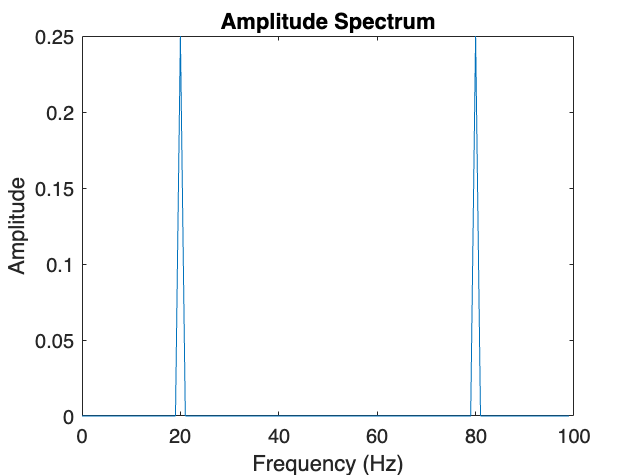


% Plot the amplitude spectrum
figure;

% We know that The FFT produces a symmetric spectrum. So we can have:
% plot(frequencies(1:floor(n/2)), amplitude(1:floor(n/2)));

% But no problem if we use this instead, which is simpler to understand
plot(frequencies, amplitude);

title('Amplitude Spectrum');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

we know that:

𝑦 ( 𝑡 ) = 𝛼 cos ( ( 2 𝜋 ( 𝑓 𝑐 + 𝑓 𝑑 ) 𝑡 − ( 2 𝜋 ( 𝑓 𝑐 + 𝑓 𝑑 ) 𝑡 𝑑 ) ) 

𝑦 ( 𝑡 ) = 𝛼 cos ( 2 𝜋 𝑓 𝑛𝑒𝑤 + 𝜑 𝑛𝑒𝑤 )

 𝑓 𝑛𝑒𝑤  =  ( 𝑓 𝑐 + 𝑓 𝑑 )

 𝜑 𝑛𝑒𝑤 = − 2 𝜋 ( 𝑓 𝑐 + 𝑓 𝑑 ) 𝑡 𝑑 = − 2 𝜋 ( 𝑓 𝑛𝑒𝑤 ) 𝑡 𝑑 

fnew = main_frequency;

fdnew = fnew - fc;
tdnew = main_phase / (-2*pi*fnew);

rnew = tdnew / p;
vnew = fdnew / b;

disp(['fd: ', num2str(fdnew), ' Hz']);

fd: 15 Hz


disp(['td: ', num2str(tdnew), ' radians']);

td: 0.0016678 radians


disp(['r: ', num2str(rnew/1000), ' km']);

r: 250 km


disp(['v: ', num2str(vnew*3.6), ' km/h']);

v: 180 km/h


### Q4

کد زیر شامل دو بخش اصلی است: 

- محاسبه فرکانس و فاز غالب سیگنال دریافتی با استفاده از تبدیل فوریه (FFT).

- محاسبه فاصله و سرعت جسم با استفاده از فرکانس و فاز استخراج شده

function [main_phase, main_frequency] = calc_main_freq_and_phase(y, fs)
    % Input:
    % y  - Input signal
    % fs - Sampling frequency (Hz)

    % Perform FFT
    Y = fft(y);
    n = length(y); % Number of samples
    
    % Frequency vector (only positive frequencies)
    frequencies = (0:n/2-1) * (fs / n);
    % frequencies = (0:n-1) * (fs / n);
    
    % Amplitude spectrum (normalized)
    amplitude = abs(Y(1:n/2)) / n; % Only positive half
    % amplitude = abs(Y) / n;

    % Find the main frequency
    [~, idx] = max(amplitude); 
    main_frequency = frequencies(idx);

    % Extract phase
    phase_spectrum = angle(Y(1:n/2)); % Only positive half
    main_phase = phase_spectrum(idx);
end

Noise Level: 0.001


New Radius (rnew): 249.5719 km


New Velocity (vnew): 180 km/h


------------------------------------


Noise Level: 0.005


New Radius (rnew): 246.0796 km


New Velocity (vnew): 180 km/h


------------------------------------


Noise Level: 0.01


New Radius (rnew): 247.7917 km


New Velocity (vnew): 180 km/h


------------------------------------


Noise Level: 0.05


New Radius (rnew): 240.6818 km


New Velocity (vnew): 180 km/h


------------------------------------


Noise Level: 0.1


New Radius (rnew): 251.7434 km


New Velocity (vnew): 180 km/h


------------------------------------


Noise Level: 0.2


New Radius (rnew): 220.674 km


New Velocity (vnew): 180 km/h


------------------------------------


Noise Level: 0.3


New Radius (rnew): 237.6879 km


New Velocity (vnew): 180 km/h


------------------------------------


Noise Level: 0.5


New Radius (rnew): 380.4113 km


New Velocity (vnew): 180 km/h


------------------------------------


Noise Level: 1


New Radius (rnew): 107.5812 km


New Velocity (vnew): 180 km/h


------------------------------------


Noise Level: 1.5


New Radius (rnew): 630.1962 km


New Velocity (vnew): 180 km/h


------------------------------------


Noise Level: 2


New Radius (rnew): 1364.7188 km


New Velocity (vnew): 504 km/h


------------------------------------


Noise Level: 5


New Radius (rnew): 8979.8462 km


New Velocity (vnew): -12 km/h


------------------------------------


این تابع `calc_main_freq_and_phase` فرکانس و فاز غالب سیگنال  دریافتی را محاسبه می‌کند. ابتدا تبدیل فوریه سیگنال انجام می‌شود و سپس  طیف دامنه و فاز محاسبه می‌شود. فرکانس و فاز غالب با یافتن پیک طیف دامنه  به دست می‌آید.

function [rnew, vnew] = calc_r_and_v(pnew, fnew, fc, p, b)
    
    fdnew = fnew - fc;
    tdnew = pnew / (-2*pi*fnew);
    
    rnew = tdnew / p;
    vnew = fdnew / b;
end

این تابع `calc_r_and_v` فاصله و سرعت جسم را با استفاده از  فرکانس و فاز غالب محاسبه می‌کند. فرکانس داپلر و تاخیر زمانی جدید محاسبه  شده و سپس فاصله و سرعت جدید به دست می‌آید.

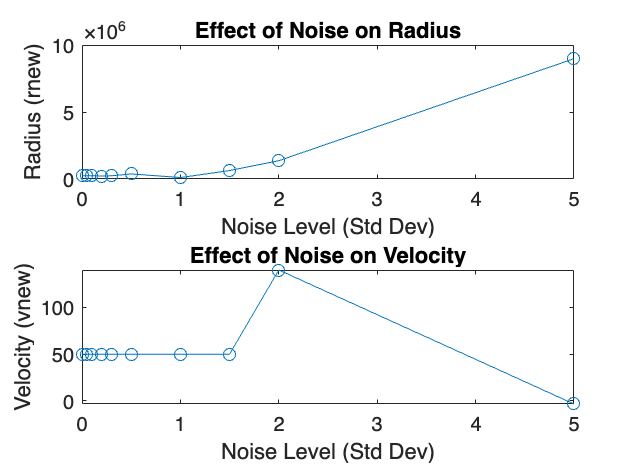

noise = 0.1 * randn(size(y)); % Generate Gaussian noise with standard deviation 0.1
ynew = y + noise; % Add noise to the signal

[pnew, fnew] = calc_main_freq_and_phase(ynew,fs);

[rnew, vnew] = calc_r_and_v(pnew, fnew, fc, p, b);

- **تولید نویز و افزودن به سیگنال:**

- نویز گوسی با انحراف معیار 0.1 تولید شده و به سیگنال دریافتی اضافه می‌شود.

- سپس فرکانس و فاز غالب سیگنال نویزی محاسبه می‌شود.

- **تعریف سطوح نویز:**

- سطوح مختلف نویز از 0.001 تا 5 تعریف می‌شوند.

- **حلقه برای بررسی سطوح مختلف نویز:**

- در این حلقه، نویز با سطوح مختلف تولید و به سیگنال اضافه می‌شود.

- فرکانس و فاز غالب برای هر سیگنال نویزی محاسبه می‌شود.

- فاصله و سرعت جدید با استفاده از فرکانس و فاز محاسبه شده به دست می‌آیند.

- نتایج برای هر سطح نویز ذخیره و نمایش داده می‌شود.

- **رسم نتایج برای تحلیل:**

- نتایج فاصله و سرعت با توجه به سطوح نویز مختلف رسم می‌شوند تا تأثیر نویز بر این پارامترها نمایش داده شود

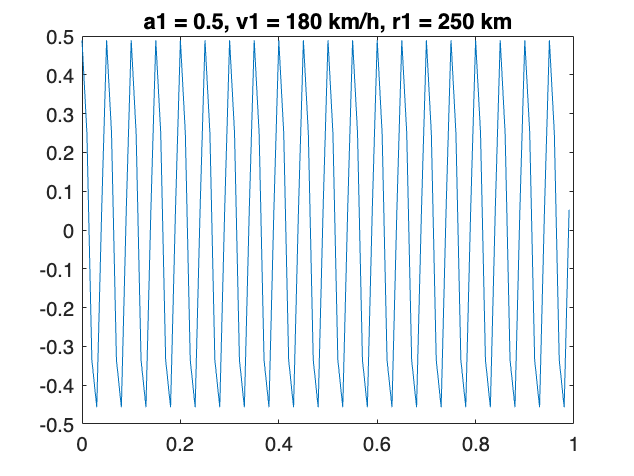

% Define noise levels
noise_levels = [0.001, 0.005, 0.01, 0.05, 0.1, 0.2, 0.3, 0.5, 1, 1.5, 2, 5]; % Standard deviations of noise

% Preallocate arrays to store results
rnew_results = zeros(size(noise_levels));
vnew_results = zeros(size(noise_levels));

% Loop through different noise levels
for i = 1:length(noise_levels)
    % Generate noise and add to the signal
    noise = noise_levels(i) * randn(size(y)); % Gaussian noise
    ynew = y + noise; % Add noise to the signal

    % Calculate the main frequency and phase for the noisy signal
    [pnew, fnew] = calc_main_freq_and_phase(ynew, fs);

    % Calculate rnew and vnew using the derived frequency and phase
    [rnew, vnew] = calc_r_and_v(pnew, fnew, fc, p, b);

    % Store the results
    rnew_results(i) = rnew;
    vnew_results(i) = vnew;

    % Display results for this noise level
    disp(['Noise Level: ', num2str(noise_levels(i))]);
    disp(['New Radius (rnew): ', num2str(rnew/1000), ' km']);

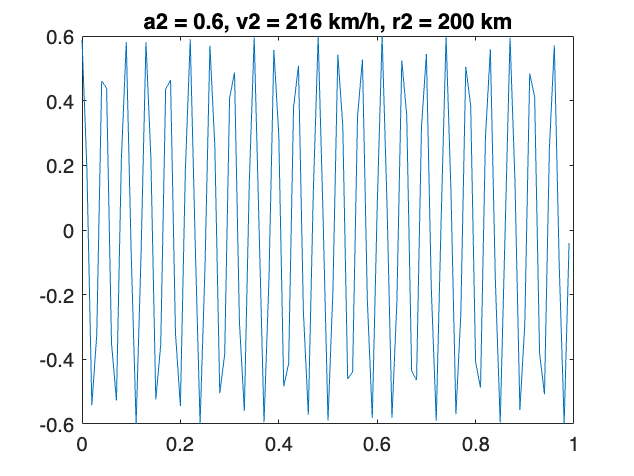

    disp(['New Velocity (vnew): ', num2str(vnew*3.6), ' km/h']);
    disp('------------------------------------');
end


% Optionally, plot the results for analysis
figure;
subplot(2, 1, 1);
plot(noise_levels, rnew_results, '-o');
xlabel('Noise Level (Std Dev)');
ylabel('Radius (rnew)');

title('Effect of Noise on Radius');

subplot(2, 1, 2);
plot(noise_levels, vnew_results, '-o');
xlabel('Noise Level (Std Dev)');
ylabel('Velocity (vnew)');
title('Effect of Noise on Velocity');

**نتیجه‌گیری**

با اجرای کد و افزودن سطوح مختلف نویز به سیگنال دریافتی، مشاهده می‌کنیم که:

- فاصله (rnew) به نویز حساس‌تر است و با افزایش سطح نویز به مقدار 0.2  یا بیشتر، خطا در محاسبه فاصله به طور قابل توجهی افزایش می‌یابد.

- سرعت (vnew) نسبت به نویز مقاوم‌تر است و تا سطح نویز 1 یا بیشتر، خطا در محاسبه سرعت کمتر تحت تأثیر قرار می‌گیرد.

این نتایج نشان می‌دهد که پارامتر فاصله نسبت به نویز حساسیت بیشتری  دارد و در حضور نویز بالا، دقت محاسبه فاصله کاهش می‌یابد، در حالی که  محاسبه سرعت نسبت به نویز مقاوم‌تر است.

### Q5

**توضیحات کد**

- **تعریف پارامترها:**

- ضریب تضعیف، سرعت و فاصله جسم اول و دوم

- ضریب داپلر، سرعت نور و ضریب تبدیل فاصله به زمان

- فرکانس سیگنال ارسالی و فرکانس نمونه‌برداری

- بازه زمانی و بردار زمان

- **محاسبه فرکانس داپلر و تاخیر زمانی:**

- فرکانس داپلر و تاخیر زمانی برای هر جسم محاسبه می‌شود.

- **تعریف سیگنال‌های دریافتی:**

- سیگنال دریافتی از هر جسم با استفاده از فرکانس و تاخیر زمانی محاسبه می‌شود.

- **رسم سیگنال‌های دریافتی:**

- سیگنال دریافتی از هر جسم به صورت جداگانه رسم می‌شود.

- **مجموع سیگنال‌های دریافتی:**

- مجموع سیگنال‌های دریافتی از دو جسم محاسبه و رسم می‌شود.

**نتیجه‌گیری**

نمودارهای رسم شده نمایش‌دهنده سیگنال‌های دریافتی از دو جسم مختلف و  مجموع آن‌ها است. این نمودارها نشان می‌دهند که سیگنال دریافتی رادار حاصل  جمع اکوهای برگشتی از دو جسم با پارامترهای مختلف است. با استفاده از این  اطلاعات، می‌توان تحلیل دقیق‌تری از وضعیت اجسام مختلف انجام داد.

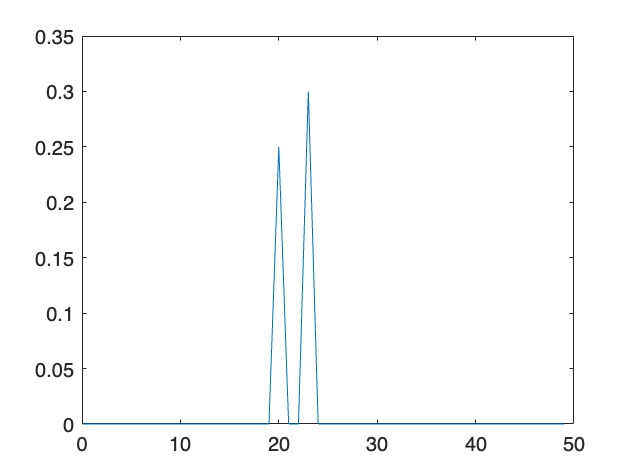

a1 = 0.5;
a2 = 0.6;

v1 = 180 / 3.6;
v2 = 216 / 3.6;

r1 = 250 * 1000;
r2 = 200 * 1000;

b = 0.3;

c = 299792458; % speed of light (m/s)
p = 2/c;

fd1 = b * v1;
td1 = p * r1;

fd2 = b * v2;
td2 = p * r2;

y1 = a1 * cos(2 * pi * (fc + fd1) * (t - td1));
y2 = a2 * cos(2 * pi * (fc + fd2) * (t - td2));

figure;

Top two frequencies:


plot(t, y1);

    23    20



title("a1 = 0.5, v1 = 180 km/h, r1 = 250 km");


Top two phases:


figure;

   -0.9127   -0.2096



plot(t, y2);
title("a2 = 0.6, v2 = 216 km/h, r2 = 200 km");

ysum = y1 + y2;

figure;
plot(t, ysum);
title("ysum");

### Q6

% Perform FFT
Y = fft(ysum);
n = length(ysum); % Number of samples

rnew1 = 9.4669e+05

vnew1 = 60

% Frequency vector (only positive frequencies)
frequencies = (0:n/2-1) * (fs / n);

% Amplitude spectrum (normalized)
amplitude = abs(Y(1:n/2)) / n; % Only positive half


rnew2 = 2.5000e+05

% Find peaks and their indices

vnew2 = 50

[peak_amplitudes, idx] = findpeaks(amplitude);

figure;
plot(frequencies, amplitude);

% Sort the peaks in descending order
[~, sorted_indices] = sort(peak_amplitudes, 'descend');

% Select the indices of the two largest peaks
top_two_idx = idx(sorted_indices(1:2));

% Get the corresponding frequencies and phases
top_two_frequencies = frequencies(top_two_idx);
top_two_phases = phase_spectrum(top_two_idx);

% Display the results
disp('Top two frequencies:');
disp(top_two_frequencies);

disp('Top two phases:');
disp(top_two_phases);

freq1 = top_two_frequencies(1);
freq2 = top_two_frequencies(2);

phase1 = top_two_phases(1);
phase2 = top_two_phases(2);

fdnew1 = freq1 - fc;
tdnew1 = phase1 / (-2*pi*freq1);

rnew1 = tdnew1 / p
vnew1 = fdnew1 / b

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
fdnew2 = freq2 - fc;
tdnew2 = phase2 / (-2*pi*freq2);

rnew2 = tdnew2 / p
vnew2 = fdnew2 / b

### Q7

خیر

اگر سرعت دو جسم یکسان باشد، فرکانس داپلر آن‌ها نیز یکسان خواهد بود و پیک‌های فرکانسی آن‌ها در یک فرکانس اتفاق می‌افتد. در این حالت، نمی‌توانیم سیگنال‌ها را از هم تفکیک کنیم و بنابراین نمی‌توانیم سرعت و فاصله آن‌ها را به طور جداگانه تشخیص دهیم.

حداقل اختلاف سرعت بین دو جسم باید به اندازه‌ای باشد که اختلاف فرکانس داپلر آن‌ها بزرگ‌تر از حد تفکیک‌پذیری فرکانسی باشد. برای مثال، اگر حد تفکیک‌پذیری فرکانسی 1 هرتز باشد، اختلاف سرعت‌ها باید به گونه‌ای باشد که اختلاف فرکانس داپلر آن‌ها حداقل 1 هرتز باشد. 

بر اساس پروژه قبلی، اگر اختلاف سرعت‌ها 12 کیلومتر بر ساعت باشد، اختلاف فرکانس‌ها به 1 هرتز می‌رسد و پارامترها به درستی استخراج می‌شوند.

بنابراین، برای تشخیص صحیح پارامترهای دو جسم، اختلاف سرعت‌ها باید به گونه‌ای باشد که اختلاف فرکانس داپلر آن‌ها حداقل 1 هرتز باشد.

### Q8

بله، در صورتی که فاصله دو جسم برابر باشد ولی سرعت‌ها متفاوت باشد، می‌توانیم سرعت‌ها و فاصله آن‌ها را استخراج کنیم. دلیل این امر به شرح زیر است:

اگر فاصله دو جسم یکسان باشد ولی سرعت‌ها متفاوت باشد، فرکانس داپلر آن‌ها متفاوت خواهد بود. در نتیجه، پیک‌های فرکانسی آن‌ها جدا از هم خواهند بود. بعد از پیدا کردن پیک‌های فرکانسی، می‌توانیم فاز در آن فرکانس را بررسی کنیم. داشتن فاصله یکسان باعث می‌شود که فازها یکسان باشند، اما این امر مشکلی در تشخیص اجسام ایجاد نمی‌کند زیرا پیک‌های فرکانسی جدا هستند.

بنابراین، سرعت‌ها به درستی استخراج می‌شوند چون قابلیت تفکیک فرکانس‌های آن‌ها را داریم. روش فوریه به خوبی کار می‌کند زیرا پارامتر وابسته به فرکانس تغییری نکرده است.

### Q9

در صورتی که تعداد اجسام را ندانیم، می‌توان از روش زیر برای استخراج تعداد اجسام و پارامترهای آن‌ها استفاده کرد:

- **اعمال تبدیل فوریه (FFT):** ابتدا بر روی سیگنال دریافتی، تبدیل فوریه (FFT) را اعمال کنید تا به حوزه فرکانس بروید.

- **اعمال FFTSHIFT:** سپس از دستور `fftshift` استفاده کنید تا نمودار طیف فرکانسی منظم شود و فرکانس‌های مثبت و منفی به ترتیب در نیمه‌های چپ و راست قرار گیرند.

- **پیدا کردن پیک‌ها:** در نیمه دوم نمودار (قسمت مربوط به فرکانس‌های مثبت)، تعداد پیک‌ها را پیدا کنید. برای این کار می‌توانید  مقدار نمودار را در هر نقطه با نقطه قبل از آن مقایسه کنید. اگر نمودار پیک زده باشد، این مقدار بزرگ است. 

- **تعیین آستانه:** برای تشخیص پیک‌های واقعی، باید یک  آستانه تعیین کنید و اختلاف دو نقطه را با آن مقایسه کنید. این کار به دلیل وجود نویز در سیگنال ضروری است. به عنوان مثال، می‌توانید آستانه را برابر 0.1 در نظر بگیرید.

- **محاسبه تعداد اجسام:** تعداد پیک‌های پیدا شده را بر دو تقسیم کنید تا تعداد اجسام را به دست آورید.

- **استخراج پارامترها:** پس از پیدا کردن هر پیک،  می‌توانید فرکانس و فاز آن‌ها را استخراج کنید و از این اطلاعات برای  محاسبه سرعت و فاصله اجسام استفاده کنید.

**نتیجه‌گیری**

با استفاده از تبدیل فوریه و پیدا کردن پیک‌های فرکانسی در سیگنال  دریافتی و تعیین آستانه مناسب، می‌توان تعداد اجسام و پارامترهای مربوط به  آن‌ها را استخراج کرد